# III. Bubble localization

addpath("Cropped_images\Cropped_images\")

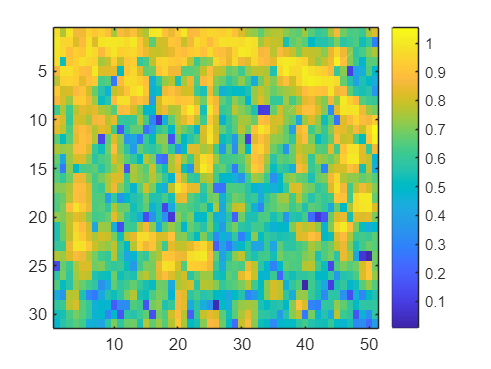

load('BF_IQ_Cropped_bloc011.mat')

X_extent = 5*10^(-3); %in m
Z_extent = 3*10^(-3);

f0 = 15625000; % ultrasound frequency


% pixel size ~ 10^(-4) m -> 2 ODG bigger than bubbles ? not normal 

size_IQF = size(IQF);
IQ_dB = zeros(size_IQF(1), size_IQF(2), size_IQF(3));

for i=1:size_IQF(3)
IQ_dB(:,:,i) = 20*log10(abs(IQF(:,:,i)));
end 

figure(1)
imagesc(sqrt(double(abs(IQ_dB(:,:,2))./max((IQ_dB(:,:,1))))))
colorbar

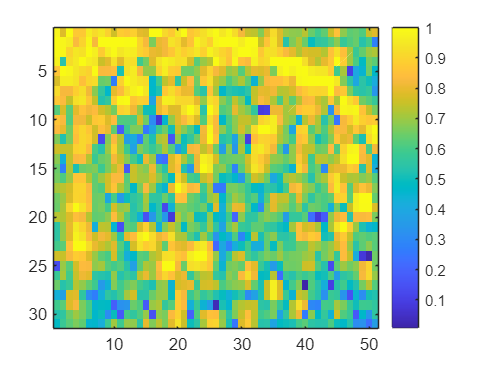



figure(2)
imagesc(sqrt(double(abs(IQ_dB(:,:,2))./max((IQ_dB(:,:,2))))))
colorbar

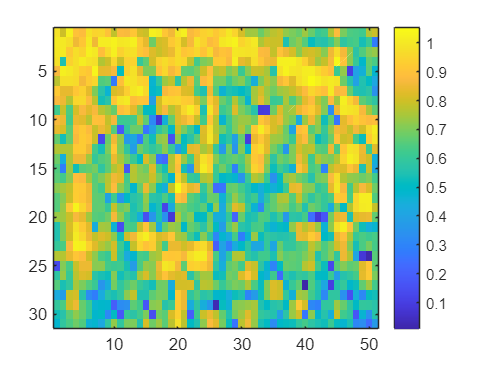



figure(3)
imagesc(sqrt(double(abs(IQ_dB(:,:,2))./max((IQ_dB(:,:,3))))))
colorbar

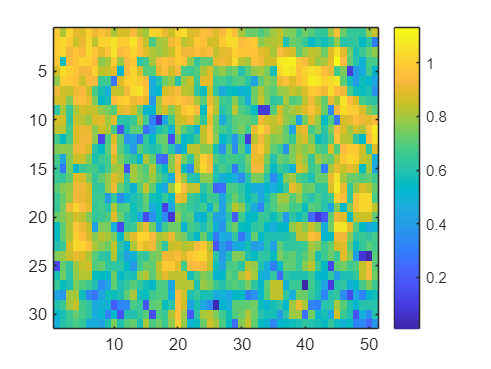



figure(4)
imagesc(sqrt(double(abs(IQ_dB(:,:,2))./max((IQ_dB(:,:,4))))))
colorbar

#### 1) Take 1 frame of 𝐼𝑄F, and find all local intensity maxima. Display those maxima on your PD image.  What do you observe?

% Take 1 frame of IQF
IQ_dB1 = IQ_dB(:,:,1) ;

pks = findLocalMaxima(IQ_dB1)

'findLocalMaxima' is not found in the current folder or on the MATLAB path, but exists in:
    E:\projetIMA

Change the MATLAB current folder or add its folder to the MATLAB path.


imagesc(IQ_dB1); hold on
   
plot(pks(:,1),pks(:,2),'r*')
